clf;

data = readtable('custom-bd.csv')

data = 161x5 table
       DATE        Dhaka    Tangail    CoxsBazar    Khagrachari
    ___________    _____    _______    _________    ___________

    07-Jul-2020      6        44          44             0     
    08-Jul-2020     23        15          22             2     
    09-Jul-2020     98        31          44            13     
    10-Jul-2020      9         7          20             0     
    11-Jul-2020     23        25          10            35     
    12-Jul-2020     51        50          25             0     
    13-Jul-2020     25        34          20            16     
    14-Jul-2020     33        31          35             0     
    15-Jul-2020     24        12          15            27     
    16-Jul-2020     19        56          16             0     
    17-Jul-2020     26        14          

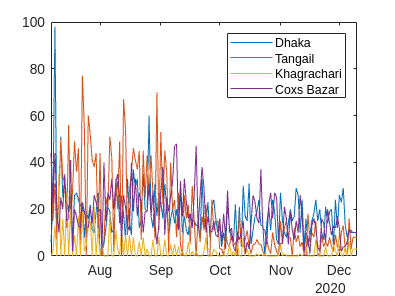



figure(1);
plot(data.DATE,[data.Dhaka,data.Tangail,data.Khagrachari,data.CoxsBazar])
xlim([datetime(2020,7,7),datetime(2020,12,10)]);
legend('Dhaka','Tangail','Khagrachari','Coxs Bazar')


totalD = sum(data.Dhaka);
totalT = sum(data.Tangail);
totalK = sum(data.Khagrachari);
totalC = sum(data.CoxsBazar);

table(totalD,totalT,totalK,totalC,'VariableNames',{'Dhaka','Tangail','Khagrachari','Coxsbazar'})

ans = 1x4 table
    Dhaka    Tangail    Khagrachari    Coxsbazar
    _____    _______    ___________    _________

    2800      2808          472          2765   
